### **The Source**

% This section initializes the source characters and generates a random sample for processing.
characters = char(32:126);
DoupleInputText = randsample(32:126, 7);
InputText = char(DoupleInputText);

### **Probability Assigner**

% This section calculates the probability of occurrence for each character in the sample.
POC = zeros(1, 7);
a = zeros(1, 7);
for j = 1:7
    a(1, j) = length(find(DoupleInputText(j) == DoupleInputText));
    POC(1, j) = a(1, j) / 7;
end

### **n-gram Probability Matrix Generator**

% This section generates an n-gram probability matrix.
POC = [POC zeros(1, 16800)];
lop = length(POC);
for a = 1:4
    lop1 = length(POC(POC(a, :) > 0));
    NumberOfZeros = lop - 7^(a+1);
    POC(a+1, :) = [POC(1, 1) .* POC(a, 1:lop1), POC(1, 2) .* POC(a, 1:lop1), POC(1, 3) .* POC(a, 1:lop1), ...
                   POC(1, 4) .* POC(a, 1:lop1), POC(1, 5) .* POC(a, 1:lop1), POC(1, 6) .* POC(a, 1:lop1), ...
                   POC(1, 7) .* POC(a, 1:lop1), zeros(1, NumberOfZeros)];
end

### **The Designed Algorithm**

% Huffman coding process for each gram number.
for GramNumber = 1:4
    pvn = POC(GramNumber, :);
    ProbabilitiesVectorOfCurrentGram = pvn(pvn > 0);
    l = length(ProbabilitiesVectorOfCurrentGram);
    Temp = ProbabilitiesVectorOfCurrentGram;
    ProbabilitiesIndexTree = zeros(l, l);
    for i = 1:l-1
        [Temp, l0] = sort(Temp);
        ProbabilitiesIndexTree(i, :) = [l0(1:l-i+1), zeros(1, i-1)];
        Temp = [Temp(1) + Temp(2), Temp(3:end), 1];
    end
    TempCode = blanks(l * l);
    TreeCode = blanks(l * l);
    TempCode(l) = '0';
    TempCode(2 * l) = '1';
    position0 = 0;
    position1 = 0;
    position2 = 0;
    for i = 1:l-2
        TreeCode = TempCode;
        position0 = find(ProbabilitiesIndexTree(l-i, :) == 1) * l;
        TempCode(1:l) = [TreeCode(position0-l+2:position0) '0'];
        TempCode(l+1:2*l) = [TempCode(1:l-1) '1'];
        for j = 2:i+1
            position2 = find(ProbabilitiesIndexTree(l-i, :) == j);
            TempCode(j*l+1:(j+1)*l) = TreeCode(l*(position2-1)+1:l*position2);
        end
    end
    TempHuffmanCode = char(zeros(l, l));
    for i = 1:l
        position1 = find(ProbabilitiesIndexTree(1, :) == i);
        TempHuffmanCode(i, 1:l) = TempCode(l*(position1-1)+1:position1*l);
    end
    HuffmanCode = strtrim(TempHuffmanCode);

    % This subsection calculates the efficiency of the Huffman coding algorithm.
    disp('***********************************************************')
    disp(['Number of gram: ', num2str(GramNumber)])
    disp([' ', 'message', ' --> ', 'codeword', ' Probability']);
    CodeLength = zeros(1, l);
    for i = 1:l
        CodeLength(i) = length(find(abs(HuffmanCode(i, :)) == 48)) + length(find(abs(HuffmanCode(i, :)) == 49));
        Output = ['X', num2str(i), ' ', HuffmanCode(i, :), '', num2str(ProbabilitiesVectorOfCurrentGram(i))];
    end
    AverageCodeLength = sum(CodeLength .* ProbabilitiesVectorOfCurrentGram) / GramNumber;
    PVOFG1 = POC(1, :);
    ProbabilitiesVectorOfFirstGram = PVOFG1(PVOFG1 > 0);
    Entropy = sum(-log(ProbabilitiesVectorOfFirstGram) .* ProbabilitiesVectorOfFirstGram) / log(2);
    Efficiency(1, GramNumber) = (Entropy / AverageCodeLength) * 100;
    display(['Entropy = ', num2str(Entropy)])
    display(['Average codeword length = ', num2str(AverageCodeLength)])
    disp(['Efficiency = ', num2str(Efficiency(1, GramNumber)), ' %'])
end

***********************************************************


Number of gram: 1


 message --> codeword Probability


Entropy = 2.8074


Average codeword length = 2.8571


Efficiency = 98.2574 %


***********************************************************


Number of gram: 2


 message --> codeword Probability


Entropy = 2.8074


Average codeword length = 2.8469


Efficiency = 98.6096 %


***********************************************************


Number of gram: 3


 message --> codeword Probability


Entropy = 2.8074


Average codeword length = 2.8358


Efficiency = 98.9982 %


***********************************************************


Number of gram: 4


 message --> codeword Probability


Entropy = 2.8074


Average codeword length = 2.8235


Efficiency = 99.4278 %


### **Plot Efficiency **

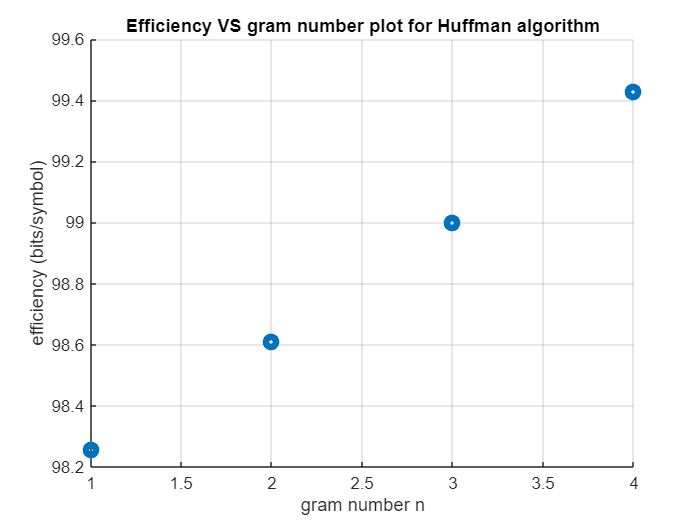

% This section creates a plot to visually compare efficiency across different n-grams.
HorizontalAxis = [1 2 3 4];
scatter(HorizontalAxis, Efficiency, "LineWidth", 4)
title('Efficiency VS gram number plot for Huffman algorithm')
xlabel('gram number n')
ylabel('efficiency (bits/symbol)')
grid